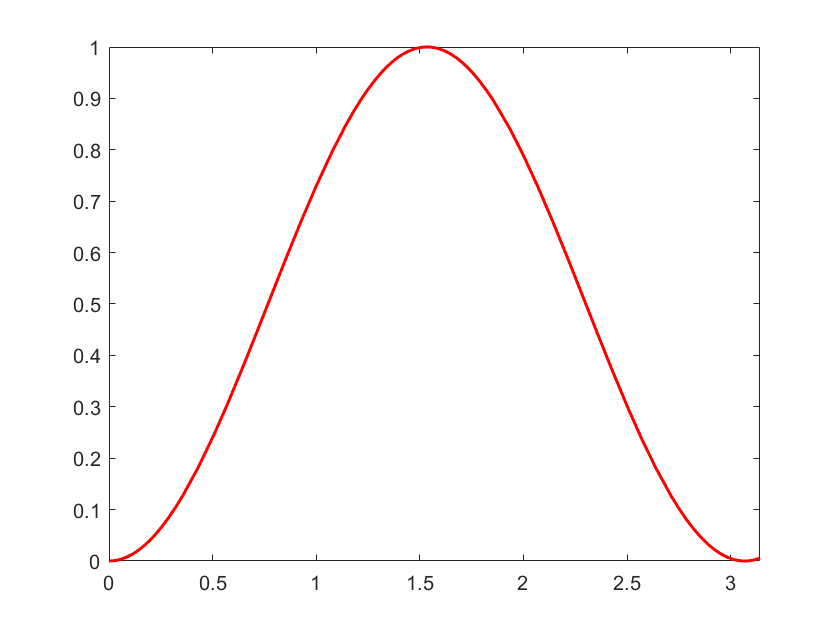

digits(12)
clf;
syms f(x);
f = sin(1.024*x)^2;
%fplot(f,'r-*')
hold off;
grid on;
fplot(@(x)sin(1.024*x).^2,'r','MarkerSize',1.5,'LineWidth',1.5)
 axis([0,pi,0,1])

p1 = linspace(0,pi,100);
p2 = linspace(0,pi,200);
p3 = linspace(0,pi,1000);
p1 = subs(f,x,p1);
p2 = subs(f,x,p2);
p3 = subs(f,x,p3);
 
s1 = vpa(mean(p1))

$$s1 = 0.483474795513$$

s2 = vpa(mean(p2))

$$s2 = 0.485899181904$$

s3 = vpa(mean(p3))

$$s3 = 0.487840164515$$

so3 = vpa(solve(f-s3,x))

$$so3 = \left(\begin{array}{c} -0.755114383735\\ 0.755114383735 \end{array}\right)$$

subs(f,x,so3)

$$ans = \left(\begin{array}{c} 0.487840164515\\ 0.487840164515 \end{array}\right)$$

jf = vpa(int(f,x,0,pi))

$$jf = 1.53412015758$$

% jf/pi == s3
% 积分中值定理